# Blockkurs Tutorial 2: Digitale Signalverarbeitung

**1. Wichtige Konzepte zu digitalen Signalen**

**    1.1 Sinuswellen**

    **1.2 Frequenz**

    **1.3 Amplitude**

    **1.4 Phase**

**    1.5 Interkative Visualisierung**

**Hinweis zu den Aufgaben**

## **1. Wichtige Konzepte zu digitalen Signalen**

Dieses Tutorial behandelt die Grundlagen der digitalen Signalverarbeitung, beginnend mit den grundlegenden Konzepten von digitalen Signalen. Da ein EEG-Signal als Überlagerung vieler Sinuswellen verstanden werden kann, ist es zentral, diese Grundform zu begreifen. Daher werden wir anhand von **Sinuswellen** lernen, was die **Frequenz**, **Amplitude** und **Phase** eines Signals sind. Ihr müsst euch keine Gleichungen merken und auch nichts auswendig lernen. Versucht einfach anhand der Beispiele die oben genannten Kernkonzepte der digitalen Signalverarbeitung zu verstehen. 

## **1.1 Sinuswellen**

Eine Sinuswelle ist eine fundamentale Signalform, die durch die Gleichung y(t) = A * sin(2 * pi * f * t + phase) beschrieben wird. Hierbei ist:

    **A** die Amplitude,

    **f** die Frequenz,

    **phase** die Phase, und

    **t** die Zeit.

Das sieht nun erst mal sehr kompliziert aus. Das müsst ihr aber auch absolut nicht auswendig lernen, es geht hier eher um das Verständnis, aus welchen Komponenten eine solche Welle besteht. Wir werden uns deshalb im Folgenden mit den Bestandteilen dieser Gleichung auseinandersetzen.

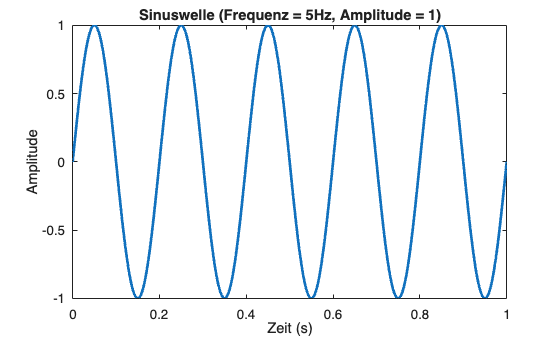

% Visualisierung einer Sinuswelle
t = 0:0.001:1; % Zeitvektor von 0 bis 1 Sekunde in Schritten von 1ms (0.001s)
f = 5; % Frequenz der Sinuswelle in Hz
A = 1; % Amplitude

% Sinuswelle berechnen
y = A * sin(2 * pi * f * t);

figure;
plot(t, y, 'LineWidth', 2);
title('Sinuswelle (Frequenz = 5Hz, Amplitude = 1)');
xlabel('Zeit (s)');
ylabel('Amplitude');

Das Diagramm zeigt eine periodische Wellenform, die bei einer **Amplitude** (y-Achse) von 0 startet und sich zwischen +1 und -1 bewegt. Die Welle erreicht innerhalb einer Sekunde fünf vollständige **Zyklen**, was einer **Frequenz** von 5 Hz entspricht. Ein Zyklus ist dabei definiert als die vollständige Bewegung der Welle von 0 nach oben, zurück nach unten und wieder auf 0. Die Anzahl der Zyklen pro Sekunde wird in Hertz (Hz) angegeben.

Keine Angst, wir schauen und das jetzt alles nochmal Schritt für Schritt an.

## **1.2 Frequenz**

Die Frequenz eines Signals beschreibt, wie oft eine Schwingung (Zyklus) pro Sekunde auftritt. Sie wird in Hertz (Hz, "Schwinungen pro Sekunde" ) gemessen.

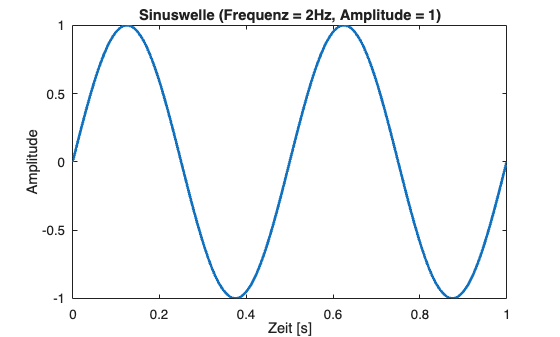

% Visualisierung einer Sinuswelle mit 2 Hz
t = 0:0.001:1; % Zeitvektor von 0 bis 1 Sekunde in Schritten von 1ms (0.001s)
f = 2; % Frequenz (Hz)
A = 1; % Amplitude

% Sinuswelle berechnen
y = A * sin(2 * pi * f * t);

% Erste Sinuswelle plotten
figure;
plot(t, y, 'LineWidth', 2);
xlabel('Zeit [s]');
ylabel('Amplitude');
title('Sinuswelle (Frequenz = 2Hz, Amplitude = 1)');

Die Sinuswelle mit einer Frequenz von 2 Hz hat also 2 Zyklen in einer Sekunde. Schauen wir uns das nochmal mit einer Frequenz von 10 Hz an.

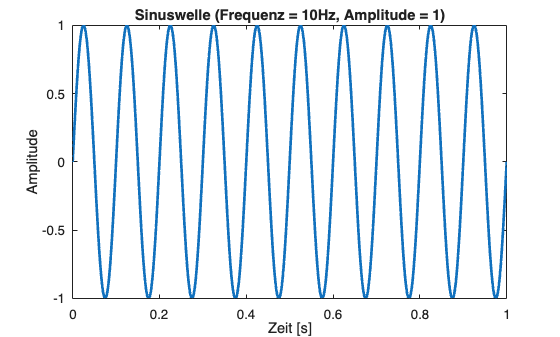

% Visualisierung einer Sinuswelle mit 10 Hz
t = 0:0.001:1; % Zeitvektor von 0 bis 1 Sekunde in Schritten von 1ms (0.001s)
f = 10; % Frequenz (Hz)
A = 1; % Amplitude

% Sinuswelle berechnen
y = A * sin(2 * pi * f * t);

% Erste Sinuswelle plotten
figure;
plot(t, y, 'LineWidth', 2);
xlabel('Zeit [s]');
ylabel('Amplitude');
title('Sinuswelle (Frequenz = 10Hz, Amplitude = 1)');

## 1.3 Amplitude

Die Amplitude (y-Achse) eines Signals gibt die maximale Ausprägung des Signals an. Sie bestimmt, wie "stark" das Signal ist. Um die Amplitudenunterschiede sichtbar zu machen, sind hier gleich drei Sinuswellen mit gleicher Frequenz, aber mit unterschiedlichen Amplituden in einer Figure geplotted.

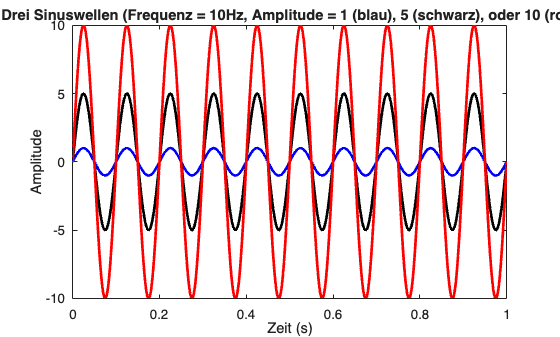

% Visualisierung von Signalen mit unterschiedlicher Amplitude
t = 0:0.001:1; % Zeitvektor von 0 bis 1 Sekunde in Schritten von 1ms (0.001s)
f = 10; % Frequenz (Hz)
A1 = 1; % Amplitude der ersten Welle: 1
A2 = 5; % Amplitude der zweiten Welle: 5
A3 = 10; % Amplitude der dritten Welle: 10

y1 = A1 * sin(2 * pi * f * t);
y2 = A2 * sin(2 * pi * f * t);
y3 = A3 * sin(2 * pi * f * t);

figure;
plot(t, y1, 'b', 'LineWidth', 2); % 'b' für blaue Linie
title('Drei Sinuswellen (Frequenz = 10Hz, Amplitude = 1 (blau), 5 (schwarz), oder 10 (rot))');
xlabel('Zeit (s)');
ylabel('Amplitude');
hold on; % Bewirkt, dass wir mehrere Signale im selben Plot darstellen können
plot(t, y2, 'k', 'LineWidth', 2); % 'k' für schwarze Linie
plot(t, y3, 'r', 'LineWidth', 2); % 'r' für rote Linie

Wir sehen hier also, dass unsere drei Sinuswellen zwar gleich viele Hügel und Täler haben - sie haben also die gleiche Frequenz - jedoch unterscheiden sie sich im Ausmass der Ausschläge nach oben und unten: der Amplitude.

## 1.4 Phase

Die Phase eines Signals beschreibt nicht die Frequenz oder Amplitude eines Sgnals, sondern wo genau wir uns gerade auf dem Zyklus einer Welle befinden (zum Beispiel gerade auf einem "Gipfel" oder im "Tal"). Zudem können zwei Signale identische Amplitude und Frequenz haben, jedoch zum Zeitpunkt 0s mit einer anderen "Phase" beginnen. Dies nennt man Phasenverschiebung. Im Folgenden wird die Phase an sich und Phasenverschiebung anhand von π und Radianten erklärt. Ihr müsst das nicht zwingend mathematisch begreifen, sondern einfach die Konzepte der Phase/Phasenverschiebung verstehen.

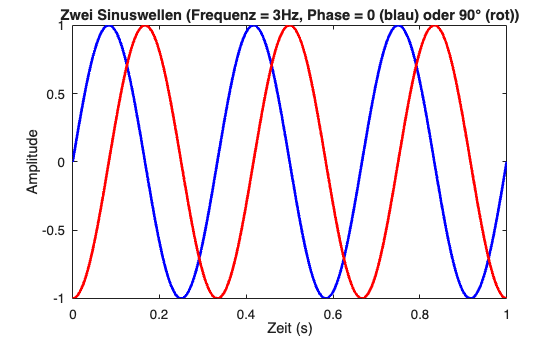

% Visualisierung von Signalen mit unterschiedlicher Phase
f = 3; % Frequenz (Hz)
phase1 = 0; % Phase 0
phase2 = pi/2; % Phase pi/2 = 180°/2 = 90°

y1 = sin(2 * pi * f * t + phase1);
y2 = sin(2 * pi * f * t - phase2);

figure;
plot(t, y1, 'b', 'LineWidth', 2);
hold on
plot(t, y2, 'r', 'LineWidth', 2);
title('Zwei Sinuswellen (Frequenz = 3Hz, Phase = 0 (blau) oder 90° (rot))');
xlabel('Zeit (s)');
ylabel('Amplitude'); 

In diesem Beispiel haben wir zwei identische Sinuswellen (in Bezug auf Frequenz und Amplitude). Die blaue Welle startet mit der Phase 0 (somit am exakten Mittelpunkt der Schwingung), die rote Welle ist jedoch phasenverschoben (hier im Beispiel um π/2 bzw. 90°). In der Visualisierung zeigt sich dies durch eine Verschiebung der roten Welle im Vergleich zur blauen Welle.

Man kann sich das wie zwei Personen vorstellen, die auf einer Schaukel sitzen: Wenn beide genau gleichzeitig schwingen, sind sie immer genau in derselben Phase. Wenn eine Person später startet, ist sie phasenverschoben.

In der Mathematik misst man diese Verschiebung mit einem Winkel in Radiant (eine Einheit für Winkel). Ein kompletter Schwingungszyklus einer Sinuswelle entspricht 2π (360°) Radiant. Eine Phasenverschiebung um π/2 (90°), wie in unserem Beispiel, bedeutet, dass die zweite Welle genau ein Viertel der Schwingung später startet. Im Plot sieht man das daran, dass die rote Welle immer 25% später ansteigt als die blaue Welle.

## 1.5 Interaktive Visualisierung

Mit den Slidern im Code unten dürft ihr für ein vertieftes Verständnis gerne etwas herumspielen, um zu sehen, wie sich die Wellen verändern, je nachdem welche Werte die Parameter Amplitude, Frequenz, oder Phase annehmen.

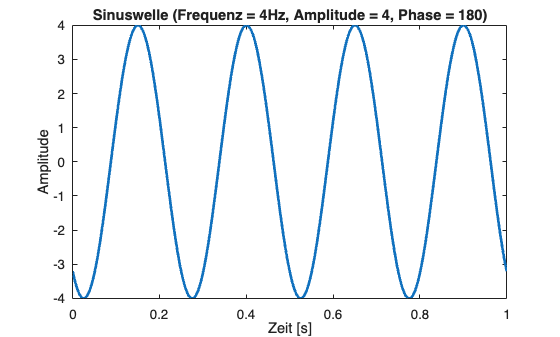

% Interaktive Visualisierung einer Sinuswelle
t = 0:0.001:1; % Zeitvektor von 0 bis 1 Sekunde in Schritten von 1ms (0.001s)
Frequenz  =4;% Frequenz in Hz (0-100)
Amplitude = 4;% Amplitude (0-25)
Phase     =180;% Phase (0-360)

% Sinuswelle berechnen
y = Amplitude * sin(2 * pi * Frequenz * t + Phase);

% Sinuswelle plotten
figure;
plot(t, y, 'LineWidth', 2);
xlabel('Zeit [s]');
ylabel('Amplitude');
title(['Sinuswelle (Frequenz = ', num2str(Frequenz) , 'Hz, Amplitude = ', num2str(Amplitude) ', Phase = ', num2str(Phase) ')']);

## Hinweise zu den Aufgaben

**Gut gemacht! Du bist nun fertig mit Tutorial 2! **Jetzt verstehst du die Grundlagen der digitalen Signalverarbeitung. 

Als Vorbereitung für den Blockkurs sollst du jetzt deine neuen Programmierkenntnisse anhand einiger Aufgaben üben. Dazu gibt es noch einen kleinen Hinweis: Wir werden nicht weiter in Live-Skripten mit dem Live-Editor arbeiten. Im Gegensatz zum Live-Skript werden in normalen MATLAB-Skripten nicht mehr der Ouput und die Plots direkt angezeigt. Du wirst dich schnell daran gewöhnen. Falls dich interessiert, was sich in einer Variable versteckt, kannst du dir mit den gelernten Methoden (Name im command window eingeben oder mit disp()) den Inhalt anzeigen lassen. 

Ausserdem haben wir im normalen Modus jetzt Platz für eine zusätzliche Spalte: den 'Workspace' (siehe Bild unten). Im Workspace-Fenster siehst du alle aktuell in MATLAB gespeicherten Variablen. Auch hier kannst du nachschauen, was sich hinter Variablennamen versteckt. Falls du einmal die Übersicht verlierst und die Standardeinstellungen wieder herstellen möchtest, kannst du im Tab 'Home' auf 'Layout' und dann auf 'Three Columns' klicken. 

Jetzt wünschen wir dir viel Erfolg bei den Aufgaben! Falls du Probleme hast, melde dich bitte einfach bei Arne.